## Φόρτωση Εικόνας

% MATLAB Script: Προσθήκη Gaussian Θορύβου με SNR=10dB & Wiener Αποκατάσταση (5.1)
clc; clear; close all;
% 1. Φόρτωση εικόνας (rgb ή grayscale)
imgRGB = imread(fullfile('Images','Ασκηση 5','new_york.png'));
if size(imgRGB,3)==3
    I = rgb2gray(imgRGB);
else
    I = imgRGB;
end
I = double(I);  % μετατροπή σε double για ακριβείς υπολογισμούς

## Δημιουργία Θορύβου και θορυβώδη εικόνα

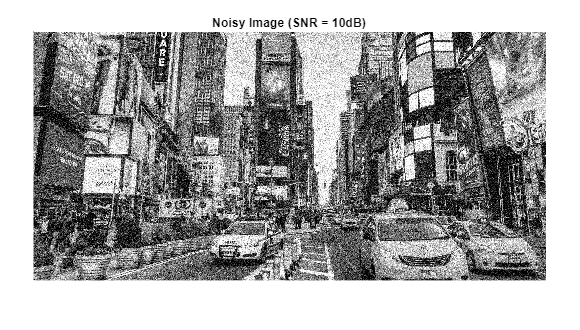


% 2. Υπολογισμός ισχύος σήματος
P_signal = mean(I(:).^2);

% 3. Επιθυμητό SNR (σε dB) και αντίστοιχη ισχύς θορύβου
SNR_dB = 10;
P_noise = P_signal / (10^(SNR_dB/10));
sigma_noise = sqrt(P_noise);

% 4. Δημιουργία και προσθήκη Gaussian θορύβου
rng(0);  % για αναπαραγωγιμότητα
noise = sigma_noise * randn(size(I));
I_noisy = I + noise;

% 5. Προσαρμογή εύρους και εμφάνιση θορυβώδους εικόνας
I_noisy_clipped = uint8(min(max(I_noisy,0),255));
figure('Name','5.1.1 Προσθήκη Gaussian Θορύβου','NumberTitle','off');
imshow(I_noisy_clipped);
title(sprintf('Noisy Image (SNR = %ddB)', SNR_dB));



## Wiener Φίλτρο – Γνωστή Ισχύς Θορύβου

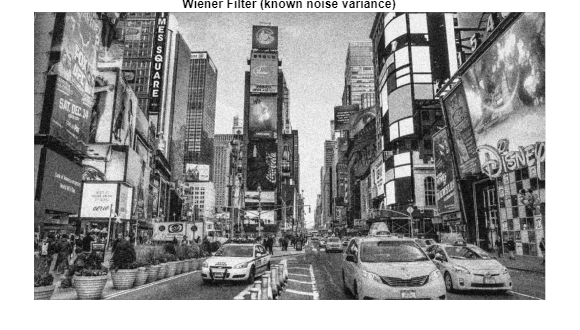


% 6.  Ερώτημα 1
noise_var = P_noise;  % γνωστή διασπορά θορύβου
I_wiener_known = wiener2(I_noisy_clipped, [5 5], noise_var);
figure('Name','5.1.2 Wiener (γνωστή ισχύς)','NumberTitle','off');
imshow(I_wiener_known);
title('Wiener Filter (known noise variance)');



## Wiener Φίλτρο – Άγνωστη Ισχύς Θορύβου

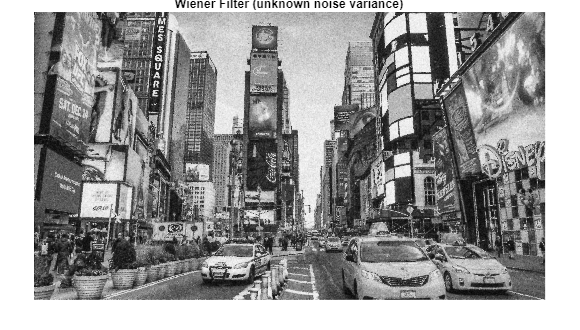


% 7. Ερώτημα 2
% Εφαρμογή Wiener φίλτρου χωρίς παροχή noise variance (εσωτερική εκτίμηση)
I_wiener_unknown = wiener2(I_noisy_clipped, [5 5]);
figure('Name','5.1.3 Wiener (άγνωστη ισχύς)','NumberTitle','off');
imshow(I_wiener_unknown);
title('Wiener Filter (unknown noise variance)');